## TP1 Telecom

close all;
clear all;

### **Initialization**

nb_bits = 2000; % On génère 2000 bits
bits = randi([0,1],1,nb_bits); % Les 2000 bits seront compris entre 0 et 1
Fe = 24000; % Fs, fréquence d'échantillonage
Rb = 6000; %débit binaire : 6000 bits / s
% Ns = Ne (echantillonage)

### **Modulateur 1**

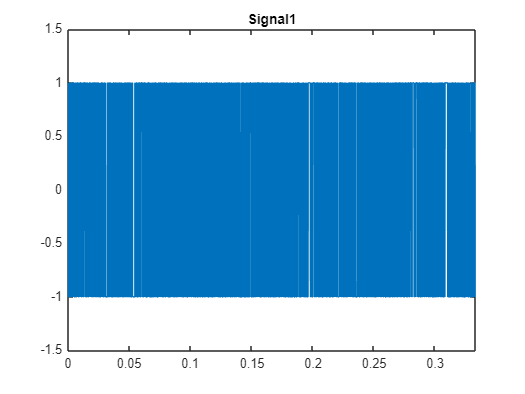

Symboles1 = 2 * bits -1; % On transforme le signal en bits de -1 et 1 
Ns1 = 4;  % Fe / Rb Chaque bit va durer 4 échantillons 
Suite_diracs1 = kron(Symboles1, [1 zeros(1,Ns1-1)]); % On créer des pics, chaque bit (-1 ou 1) est désormais suivi de 3 zéros
h1 = ones(1,Ns1); % Filtre de mise en forme rectanulaire de taille (1,Ns1)
SignalModule1 = filter(h1,1,Suite_diracs1);  % En filtrant la suite de Diracs par une porte (rect), chaque pic devient un créneau de largeur T_b    
figure('Name', 'Signal 1');
t = (0:length(SignalModule1)-1) / Fe ; % axe temps en s
plot(t, SignalModule1);
axis([0 t(end) -1.5 1.5]);
title('Signal1');

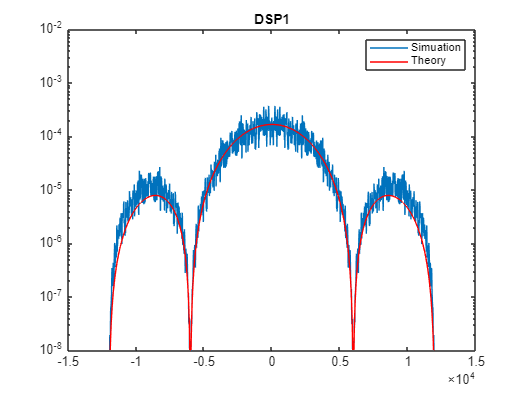

%Part of calulating and printing DSP1
figure;
DSP1_simulaire = pwelch(SignalModule1,[],[],[],Fe,'twosided', 'centered'); % pwelch : estime la Densité Spectrale de Puissance
axis_freq = linspace(-Fe/2,Fe/2,length(DSP1_simulaire));
semilogy(axis_freq,DSP1_simulaire);
hold on;
Tb = 1/Rb;
V = 1;
sigma_squared = V.^2;
DSP1_theorique = Tb * sigma_squared * sinc(axis_freq*Tb).^2;
semilogy(axis_freq,DSP1_theorique,'r');

legend('Simuation','Theory')
title('DSP1');
ylim([1e-8,1e-2]);

### **Modulateur 2**

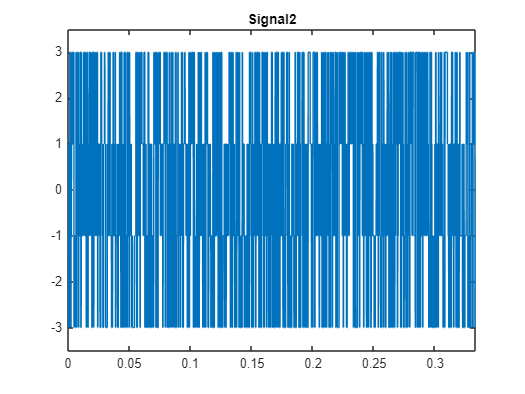

bits_reshape = reshape(bits, 2,[])'; %  On regroupe les bits 2 par 2 (00,01,10,11)
valeurs_dec = bits_reshape(:,1)*2 + bits_reshape(:,2); 
Symboles2 = (2 * valeurs_dec - 3)' ;

Ns2 = 8;
Suite_diracs2 = kron(Symboles2, [1 zeros(1,Ns2-1)]);
h2 = ones(1, Ns2);
SignalModule2 = filter(h2,1,Suite_diracs2);

t2 = (0:length(SignalModule2)-1) / Fe;
figure('Name', 'Signal 2');
plot(t2, SignalModule2);
axis([0 t2(end) -3.5 3.5]);
title('Signal2');

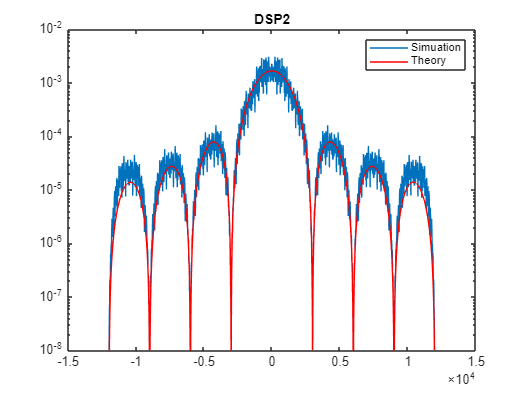


%Part of calulating and printing DSP2_Theorique
figure;
DSP2_simulaire = pwelch(SignalModule2,[],[],[],Fe,'twosided', 'centered');
axis_freq2 = linspace(-Fe/2,Fe/2,length(DSP2_simulaire));
semilogy(axis_freq2,DSP2_simulaire);
hold on;
sigma_squared2 = 5;
Tb2 = Ns2/Fe;
DSP2_theorique = sigma_squared2 * Tb2 * sinc(axis_freq2*Tb2).^2 ;
semilogy(axis_freq2,DSP2_theorique,'r');
legend('Simuation','Theory')
title('DSP2');
ylim([1e-8,1e-2]);

### Modulateur 3

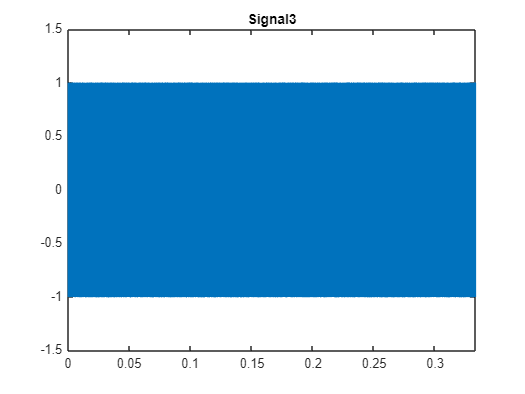

Symboles3 = 2 * bits -1;
Ns3 = 4; % Initiallement à 3, par entièrement certain mais semble plus logique.
Suite_diracs3 = kron(Symboles3, [1 zeros(1,Ns3-1)]);

h3 = [-ones(1, floor(Ns3/2)) ones(1, ceil(Ns3/2))];

SignalModule3 = filter(h3,1,Suite_diracs3);
figure('Name', 'Signal 3');
t3 = (0:length(SignalModule3)-1) / Fe;
plot(t3, SignalModule3);
axis([0 t3(end) -1.5 1.5]);
title('Signal3');

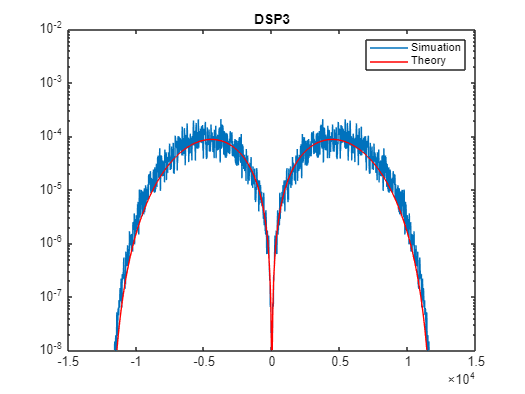

%Part of calulating and printing DSP3
figure;
DSP3_simulaire = pwelch(SignalModule3,[],[],[],Fe,'twosided', 'centered');
axis_freq3 = linspace(-Fe/2,Fe/2,length(DSP3_simulaire));
semilogy(axis_freq3,DSP3_simulaire);
hold on;

Tb3 = Ns3/Fe;
DSP3_theorique = Tb3 * (sinc(axis_freq3*Tb3/2).^2) .* (sin(pi*axis_freq3*Tb3/2).^2); 
semilogy(axis_freq3,DSP3_theorique,'r');
legend('Simuation','Theory')
title('DSP3');
ylim([1e-8,1e-2]);

### Modulateur 4

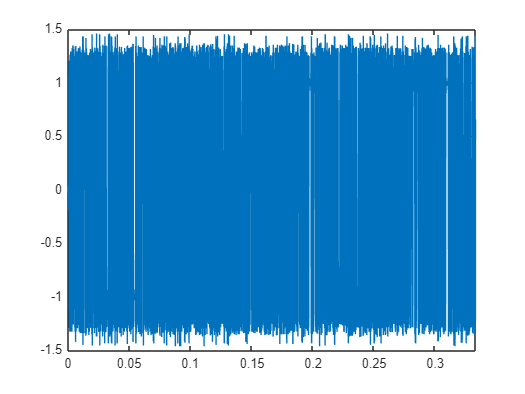

Symboles4 = 2 * bits -1;
Ns4 = 4;
Suite_diracs4 = kron(Symboles4, [1 zeros(1,Ns4-1)]);
h4 = 2*rcosdesign(0.5,8,Ns4,'sqrt'); % initiallement *2 et possiblement nécessaire de faire Ns4-1

SignalModule4 = filter(h4,1,Suite_diracs4);
figure('Name', 'Signal 4');

t4 = (0:length(SignalModule4)-1) / Fe ; % axe temps en s

plot(t4, SignalModule4);
axis([0 t4(end), -1.5 1.5]);

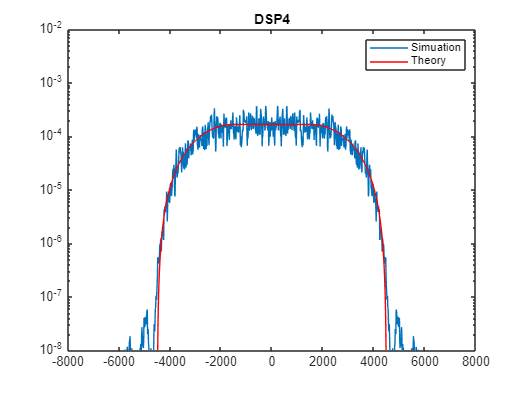

%Part of calulatting and printing DSP4_Simulaire
DSP4_simulaire = pwelch(SignalModule4,[],[],[],Fe,'twosided', 'centered');
axis_freq4 = linspace(-Fe/2,Fe/2,length(DSP4_simulaire));
semilogy(axis_freq4,DSP4_simulaire);
hold on;
alpha = 0.5;
Tb4= Ns4/Fe;

DSP4_theorique = zeros(size(axis_freq4));

% On calcule les limites de fréquences du filtre
f1 = (1 - alpha) / (2 * Tb4);
f2 = (1 + alpha) / (2 * Tb4);


for i = 1:length(axis_freq4)
    abs_f = abs(axis_freq4(i));
    if abs_f <= f1
        DSP4_theorique(i) = Tb4;
    elseif abs_f>= f1 && abs_f <= f2
        DSP4_theorique(i) = (Tb4/2) * (1 + cos((pi * Tb4 / alpha) * (abs_f - f1)));
    else
        DSP4_theorique(i) = 0;
    end
end

%DSP4_theorique = ;
semilogy(axis_freq4,DSP4_theorique,'r');
legend('Simuation','Theory')
title('DSP4');
ylim([1e-8,1e-2]);

### Compare

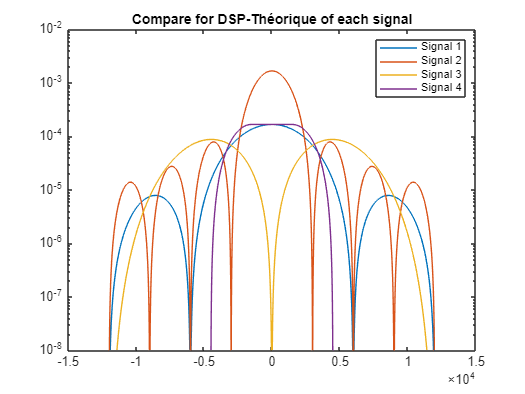

figure('Name', 'DSP-Simulaire');
semilogy(axis_freq,DSP1_theorique);
hold on;
semilogy(axis_freq2,DSP2_theorique);
hold on;
semilogy(axis_freq3,DSP3_theorique);
hold on;
semilogy(axis_freq4,DSP4_theorique);
title('Compare for DSP-Théorique of each signal')
legend('Signal 1', 'Signal 2', 'Signal 3', 'Signal 4');
ylim([1e-8,1e-2]);